# The Flatlands Challenge

#### Authors: Dexter Friis-Hecht, Dokyun Kim, Ellen Sun

!!! MATLAB Symbolic Toolbox is required to run the livescript !!!

Given an equation of a "mountain" in 3D space, guide the Neato to the top of the mountain. The Neato starts at (-2,0,0).

The mountain is defined below.


$$z=16e^{\frac{-x^2}{2} - \frac{y^2}{2} -\frac{xy}{2}}+4e^{-(x+1.5)^2 - (y+2.5)^2}$$


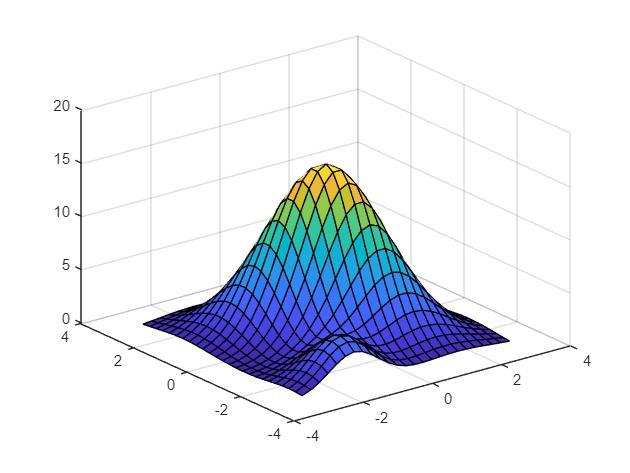

% Plot the mountain in 3D space
clf
X = -3:0.25:3;
[x,y] = meshgrid(X);
f = 16*exp(-x.^2./2-y.^2./2-x.*y./2) + 4*exp(-(x+1.5).^2 - (y+2.5).^2);
surf(x,y,f)

## Gradient Ascent/Descent

In order to program the Neato to climb the mountain, we need to use gradient ascent (or descent). 

Gradient ascent (or descent) is a technique used to determine the maximum (or minimum) of a function of many variables by taking steps in the direction of the gradient (or negative gradient).

Given a function $z = f(r)$, where $r$ is the position vector in the plane, the points determined by the gradient ascent algorithm are defined as:


$$r_{i+1} =r_i+\lambda_i\nabla f(r_i), i=0,1,2,...$$


where $\lambda_i 
$ is the step size we take in the gradient's direction. In this challenge, $\lambda_i$ will be defined as:


$$\lambda_{i+1} = \delta \lambda_i $$


where $0<\delta \leq1$.

clc, clear all
syms x y
assume(x, 'real')
assume(y, 'real')

%Function of the mountain
f = 16*exp(-x.^2./2-y.^2./2-x.*y./2) + 4*exp(-(x+1.5).^2 - (y+2.5).^2);

%Declare initial values
x_i = -2;
y_i = 0;
grad = gradient(f);
grad_i = double(subs(grad, {x, y}, {x_i, y_i}));
lambda = 0.1;
delta = 0.8;
x_arr = [x_i; 0]; %Matrix to store x positions
y_arr = [y_i; 0]; %Matrix to store y positions

## MATLAB Implementation

For the sake of implementation, we need to set an iteration limit for the gradient ascent algorithm to prevent it from going in circles near the peak. 

We set the **max_count **variable to 40 so the algorithm stops after 40 steps.

max_count = 40;

The gradient vector at the top of the mountain has a magnitude of 0. Therefore, the algorithm would run until the current gradient's magnitude reaches near 0.0001 (Accounting for error)

count = 1;
while abs(norm(grad_i)) > 0.00001 && count <= max_count
    count = count + 1;
    % Find new x & y
    x_i = x_i + lambda*grad_i(1);
    y_i = y_i + lambda*grad_i(2);

    % Update lambda
    lambda = delta * lambda; 

    % Update gradient vector
    grad_i = double(subs(grad, {x, y}, {x_i, y_i})); 

    % Append location to array
    x_arr(count) = x_i;
    y_arr(count) = y_i;
end

## Plot with planned path

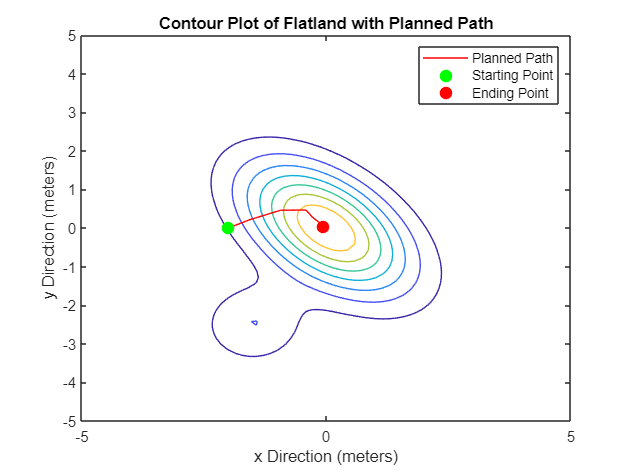

%Plot the path on a 2D contour plot of the mountain
fcontour(f)

hold on
plot(x_arr, y_arr, "r")
plot(-2, 0, "g.", "MarkerSize", 25)
plot(x_arr(end),y_arr(end),"r.","MarkerSize",25)
legend("", "Planned Path", "Starting Point", "Ending Point")
xlabel("x Direction (meters)")
ylabel("y Direction (meters)")
title("Contour Plot of Flatland with Planned Path")
hold off